# 上机练习 2

本次练习包含了线性滤波器, 卷积以及相关操作.

## 模块 1: 卷积

## 1.1编写卷积函数 (30 points)

在本小节，你需要编写两个版本的卷积函数：

- `conv_nested`

- `conv_fast`

首先，让我们先载入图片。

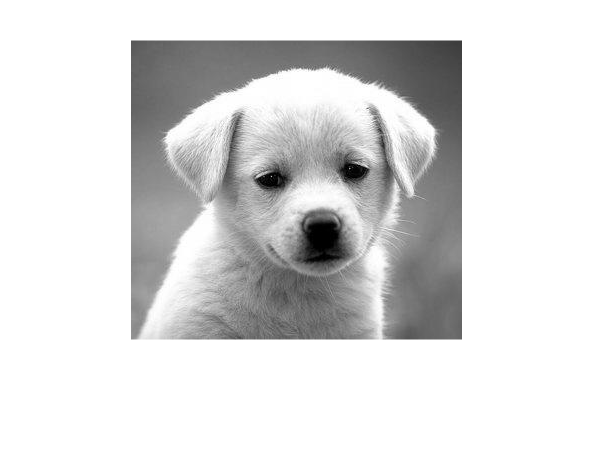

% 载入图片并转成归一化的灰度图
img = imread('dog.jpg');
img = double(rgb2gray(img))/255;

% 显示图片
imshow(img);

现在，完成并运行`conv_nested`函数.这是一个有四重循环的卷积版本。函数的输入为图像$f$以及卷积模板（卷积核）$h$，输出为卷积后的图像$f\otimes h$，输出图像的尺寸与输入图像相同。可以知道，这个版本的卷积函数速度比较慢。

*- 提示: 将函数编写成$h\otimes f$可能更容易一些*

% 首先，我们测试一下 `conv_nested` 函数是否编写正确.

% 简化版本的conv函数.
kernel = [
    [1,0,1],
    [0,0,0],
    [1,0,0]
]

kernel =      1     0     1
     0     0     0
     1     0     0


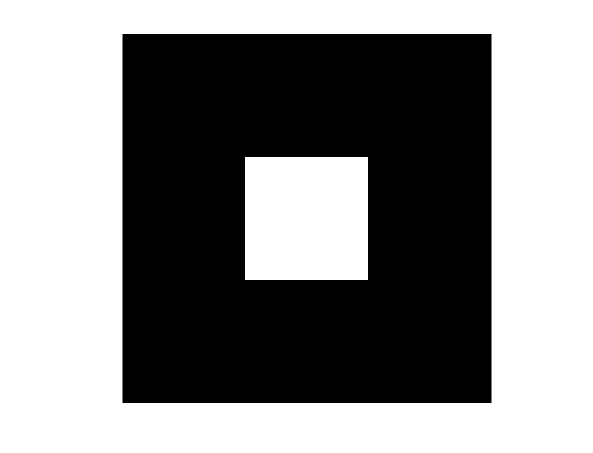


% 创建一幅测试图: 图像中间为白色色块
test_img = zeros(9,9);
test_img(4:6, 4:6) = 1;
imshow(test_img,'InitialMagnification','fit');


% 运行conv_nested函数
test_output = conv_nested(test_img, kernel);

% 写出我们所期望的结果
expected_output = zeros(9, 9);
expected_output(3:7,3:7) = 1;
expected_output(6:end,6:end) = 0;
expected_output(5,3:5) = 2;
expected_output(3:5,5) = 2;
expected_output(5,5) = 3;

% 画出原始图像
disp('原始图像：');

原始图像：


imshow(test_img,'InitialMagnification','fit');


% 
% 画出输出图像
disp('计算结果：');

计算结果：


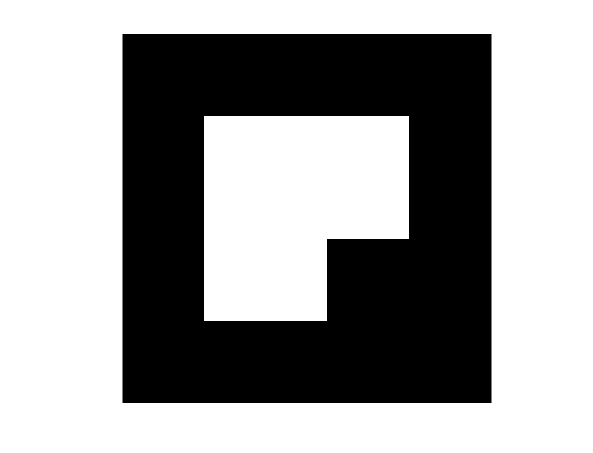

imshow(test_output,'InitialMagnification','fit');


% 画出我们期望的结果
disp('期望结果：');

期望结果：


imshow(expected_output,'InitialMagnification','fit');

% 检验下输出图像与我们期望的结果是否相同
assert (abs(sum(sum(test_output - expected_output))) < 1e-10);

现在，我们将函数 `conv_nested` 使用到实际图片中。

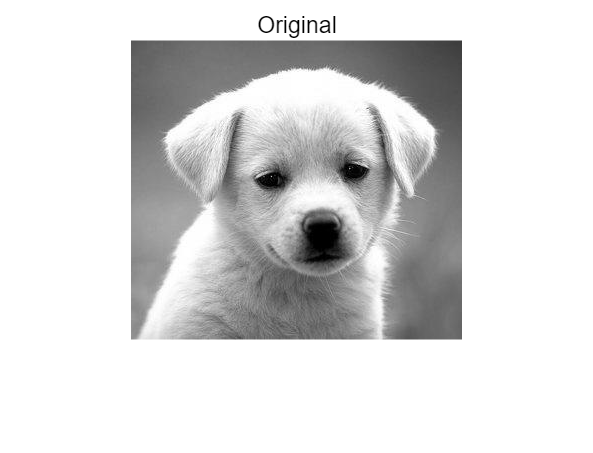

% 简单的卷积核.
% 可以尝试改变下卷积核，来看看有什么效果.
kernel = [
    [1,0,-1],
    [2,0,-2],
    [1,0,-1]
];

out = conv_nested(img, kernel);

% 画出原图
imshow(img);
title('Original');

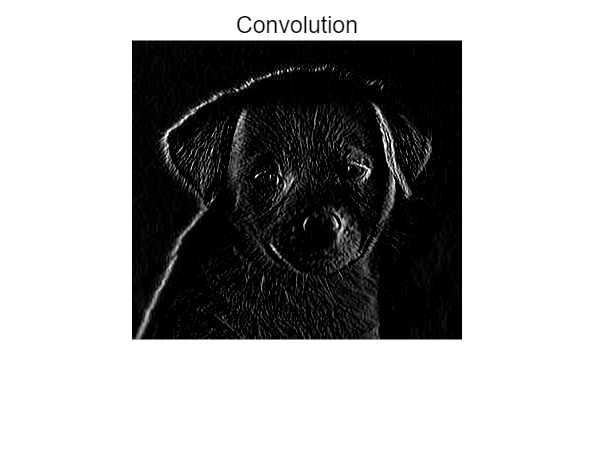



% 画出卷积后的图片
imshow(out);
title('Convolution');

现在，让我们利用矩阵操作来加速我们的卷积程序。正如课程上所说的，卷积可以看作一个（翻转后的）窗口在图片上滑动，然后对它们重合的部分计算加权平均值。因此，这个快速版本有三步：

1. 对原图片进行0填充。

2. 翻转卷积核。

3. 对图片和卷积核重合的部分计算加权平均值，作为该像素点的输出值。此时只需要用到两重循环。

首先，让我们完成并验证填充函数`zero_pad`。

pad_width = 20 % 左右两边各填充pad_width个像素点

pad_width = 20

pad_height = 40 % 上下两边各填充pad_height个像素点

pad_height = 40

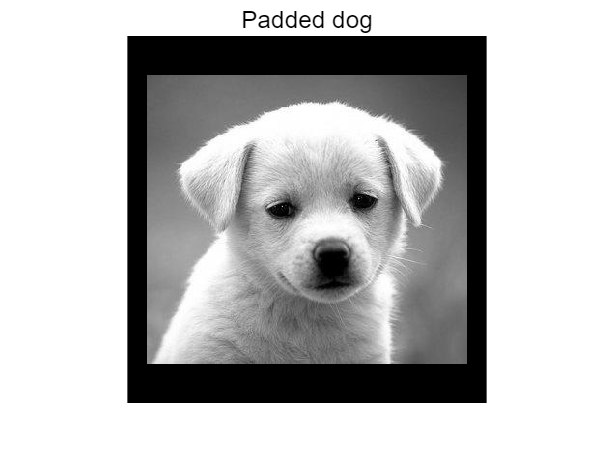


padded_img = zero_pad(img, pad_height, pad_width);

% 画出填充后的图像
imshow(padded_img,'InitialMagnification','fit');
title('Padded dog');

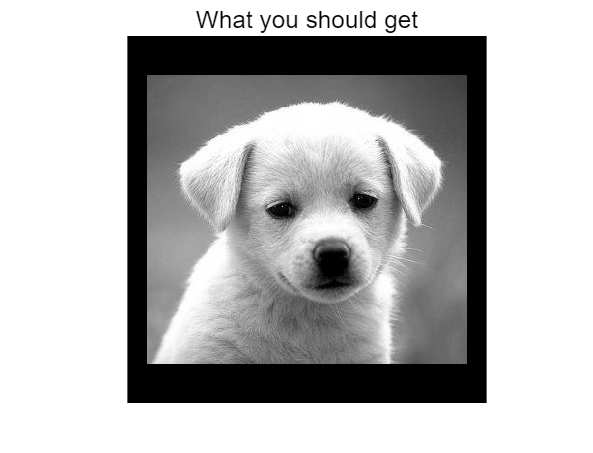


% 画出正确的结果
solution_img = imread('padded_dog.jpg');
solution_img = rgb2gray(solution_img);
imshow(solution_img,'InitialMagnification','fit');
title('What you should get');


disp('填充后的图像尺寸是: ');disp(size(padded_img));

填充后的图像尺寸是: 
   380   372



disp('我们希望的图像尺寸是:' );disp(size(solution_img));

我们希望的图像尺寸是:
   380   372



接着，让我们完成快速的卷积版本 **`conv_fast`** . 运行下面的代码来比较两个版本的卷积在速度上的差异. `conv_fast` 应该比 `conv_nested`快一些.  

通常而言, `conv_nested` 应该需要数秒的时间，而 `conv_fast`会快大约5倍。

tic;
out_fast = conv_fast(img, kernel);
toc;

历时 0.167255 秒。


tic;
out_nested = conv_nested(img, kernel);
toc;

历时 0.012425 秒。


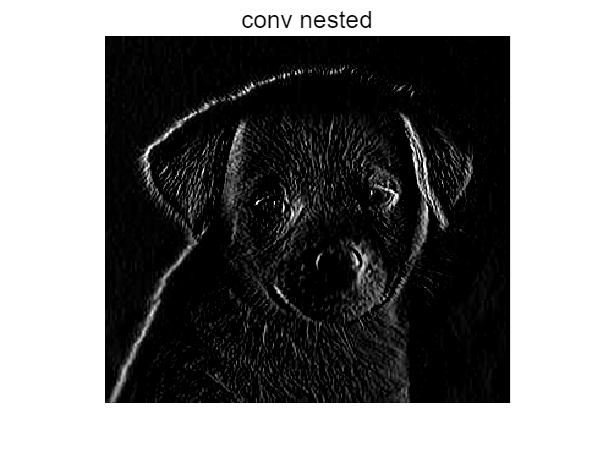


% 画出 conv_nest的结果
imshow(out_nested,'InitialMagnification','fit');
title('conv nested')

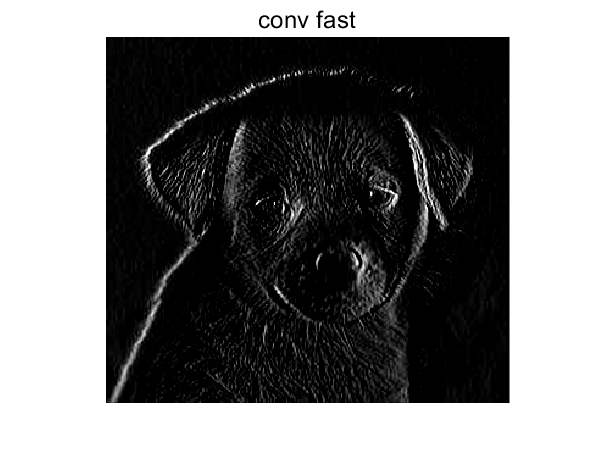


% 画出 conv_fast的结果
imshow(out_fast,'InitialMagnification','fit');
title('conv fast')


% 确保两者输出没有太大差异
if max(max(out_fast - out_nested))>1e-10
    disp('输出有误，请检查');
end

# 模块 2: 相关

两个二维信号的相关操作 $f\;\star \;g$ 可以定义为:


$$(f \star g)[m, n]=\sum_{i=-\infty}^{\infty} \sum_{j=-\infty}^{\infty} f[i, j] \cdot g[i-m, j-n]$$


## 2.1 利用相关操作进行模板匹配 

假设你是一个商店的货物管理员. 你的一个职责是定期检查货架， 如果发现某个货物售空了，则进行补货. 由于这个工作太过无聊，你决定写一个计算机视觉的程序来监视货架，缺货了自动进行提示.

幸运的是，你学习了本课程并且知道了可以利用相关操作来进行模板匹配: 模板 $g$与图像$f$ 的区域进行相关操作，可以用来度量区域与模板的相似程度。

货物的模板 (`template.jpg`) 与货架的图像 (`shelf.jpg`) 已经拍摄好了. 我们将利用相关操作寻找货物在货架上的位置.

任务：完成**`cross_correlation`** 函数并运行下列代码。

*- 提示: 可以利用你在前面所写的conv_fast函数.*

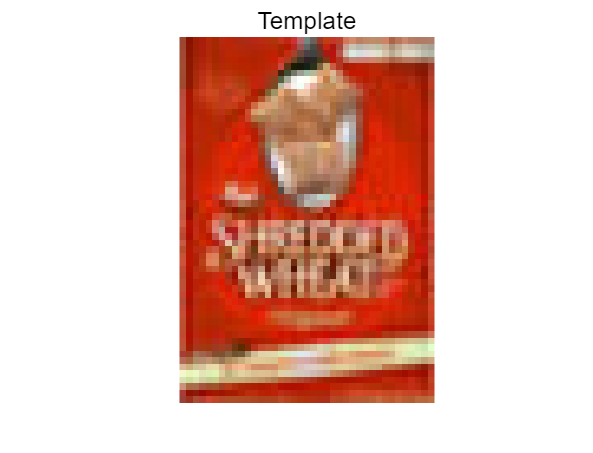

% 载入图像
img = imread('shelf.jpg');
img_grey = double(rgb2gray(img))/255;
temp = imread('template.jpg');
temp_grey = double(rgb2gray(temp))/255;

% 对图像和模板计算相关
out = cross_correlation(img_grey, temp_grey);
out = out./max(out(:));

% 找出结果里面相似度最高的点
[mdat,mpos]=max(out(:));
[x,y] = ind2sub(size(out),mpos);

% 显示模板的图片
imshow(temp,'InitialMagnification','fit');
title('Template');

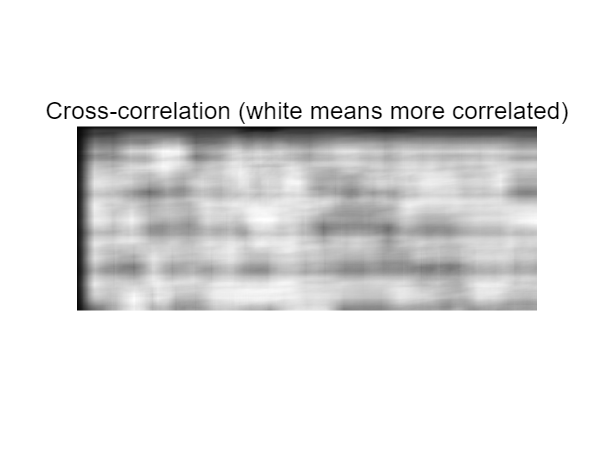


% 显示相关的结果
imshow(out,'InitialMagnification','fit');
title('Cross-correlation (white means more correlated)');

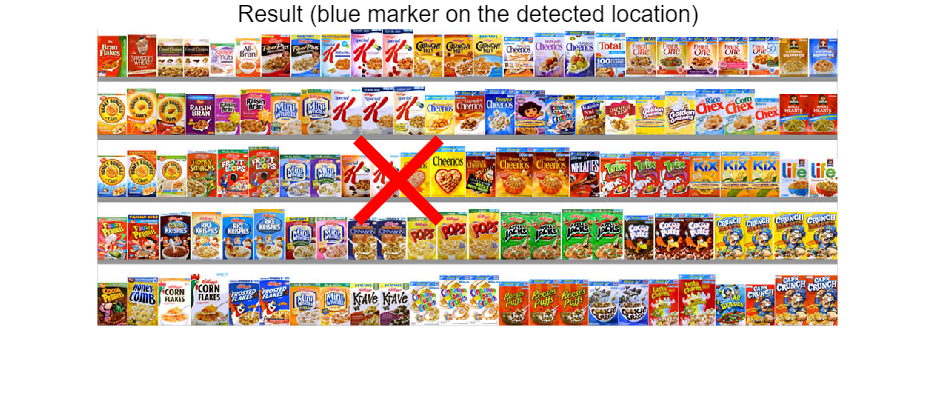


% 显示货架的图片
imshow(img);
title('Result (blue marker on the detected location)');

% 在图像中标记出相似度最高的点
hold on;
plot(y , x ,'rx','LineWidth',5,'MarkerSize',50); %记住，plot和矩阵的方向不一样

## 解释

相关操作的结果看起来好像和预期不一样? 解释一下直接使用原始的模板会存在什么问题。

你的回答：

数据有过大的均值可能会导致参数的梯度过大，零均值化是像素值域的整体平移。使用原始的模板会导致数据权重不够收敛，存在基向量正交性不明显的问题。

## 2.2 零均值相关(Zero-mean cross-correlation) (6 points)

这个问题的一个解决办法是将模板减去它的均值，使得它的均值为0。

完成**`zero_mean_cross_correlation`** 函数，然后运行下面的代码。

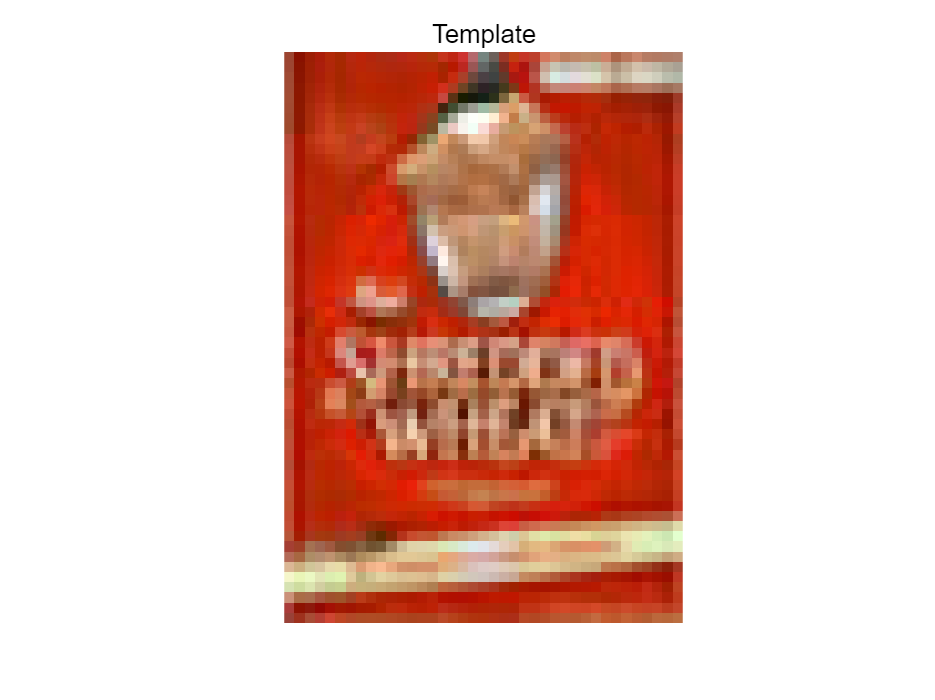

% 对图像和模板计算相关
out = zero_mean_cross_correlation(img_grey, temp_grey);
out = out./max(out(:));

% 找出结果里面相似度最高的点
[mdat,mpos]=max(out(:));
[x,y] = ind2sub(size(out),mpos);

% 显示模板的图片
figure
imshow(temp,'InitialMagnification','fit');
title('Template');

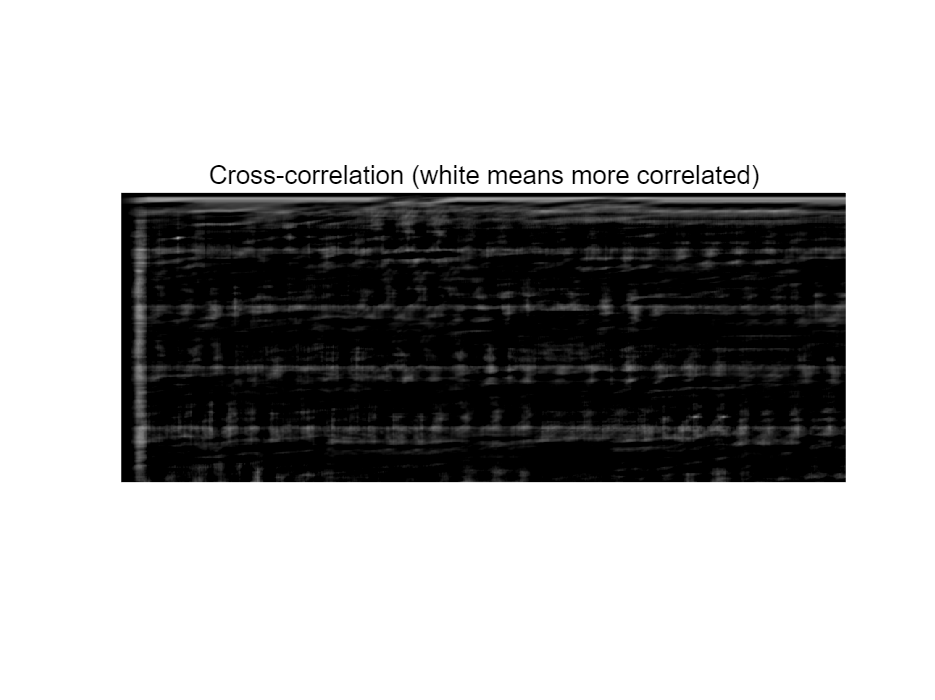


% 显示相关的结果
imshow(out,'InitialMagnification','fit');
title('Cross-correlation (white means more correlated)');

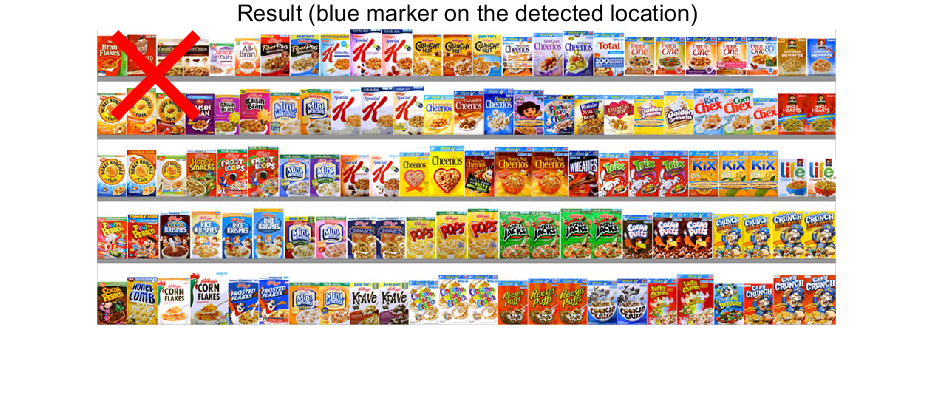


% 显示货架的图片
imshow(img);
title('Result (blue marker on the detected location)');

% 在图像中标记出相似度最高的点
hold on;
plot(y , x ,'rx','LineWidth',5,'MarkerSize',50); %记住，plot和矩阵的方向不一样

## 2.3 归一化相关 (12 points)

某一天，货架的照明光源突然无法正常工作了，而你所写的产品监控算法也突然失灵了。这是因为，你所写的零均值互相关算法对于照明变化并不健壮(roubust). 下列代码表明了这个现象：

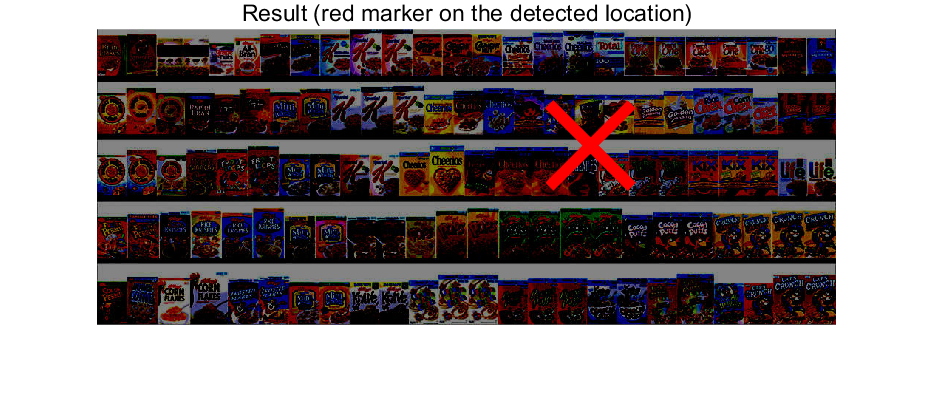

% 载入暗环境图片
img = imread('shelf_dark.jpg');
img_grey = double(rgb2gray(img))/255;

% 计算零相关响应
out = zero_mean_cross_correlation(img_grey, temp_grey);

% 找出相似性最大的点的坐标
[mdat,mpos]=max(out(:));
[x,y] = ind2sub(size(out),mpos);

% 显示图片
figure;
imshow(img);
title('Result (red marker on the detected location)');

% 显示相似度最大点的坐标
hold on;
plot(y , x ,'rx','LineWidth',5,'MarkerSize',50); %记住，plot和矩阵的方向不一样

解决该问题的一个办法是求相关之前，对图片以及模板先进行归一化. 这个方法被称作 归一化相关(Normalized cross-correlation).

我们可以用数学公式对这这一步进行描述,其中$f$表示图片，而$g$表示模板：


$$(f \star g)[m, n]=\sum_{i, j} \frac{f[i, j]-\overline{f_{m, n}}}{\sigma_{f_{m, n}}} \cdot \frac{g[i-m, j-n]-\bar{g}}{\sigma_{g}}$$


其中:

- $f_{m,n}$ 表示点 $\left(m,n\right)$的小图(patch image)，它是从原图片中分割出来的、和模板图片大小一样的，且中心点在m,n的图片

-  $\bar{f_{m,n} }$表示图片$f_{m,n}$的均值

- $\sigma_{f_{m,n} }$ 表示图片 $f_{m,n}$ 的标准差

- $\bar{g}$表示模板 $g$ 的平均值

- $\sigma_g$ 表示模板 $g$的标准差

现在请完成**`normalized_cross_correlation`** 函数并运行下列代码.

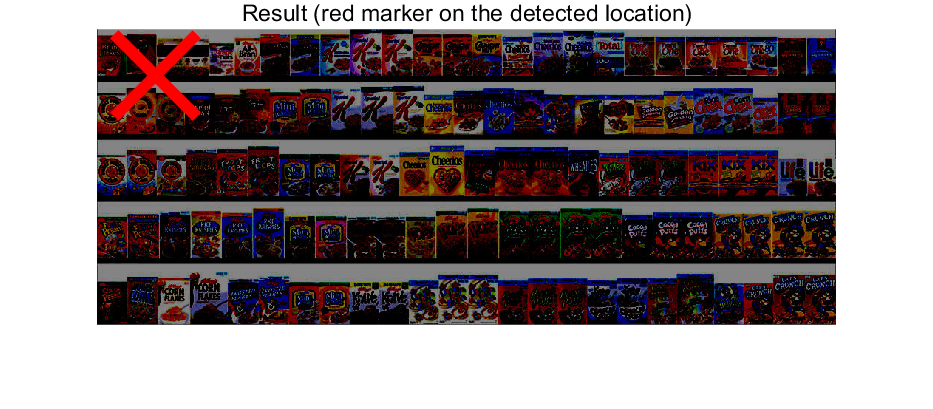

% 运行归一化相关
out = normalized_cross_correlation(img_grey, temp_grey);

% 找到相似度最大的点
[mdat,mpos]=max(out(:));
[x,y] = ind2sub(size(out),mpos);

% 显示图片
figure;
imshow(img);
title('Result (red marker on the detected location)');

% 显示相似度最大点的坐标
hold on;
plot(y , x ,'rx','LineWidth',5,'MarkerSize',50); %记住，plot和矩阵的方向不一样